# 下浮率预测模型：SVM

#### 资质要求、最高报价、下浮率、工资、开标时间、镇区、计划工期 → P值下浮率

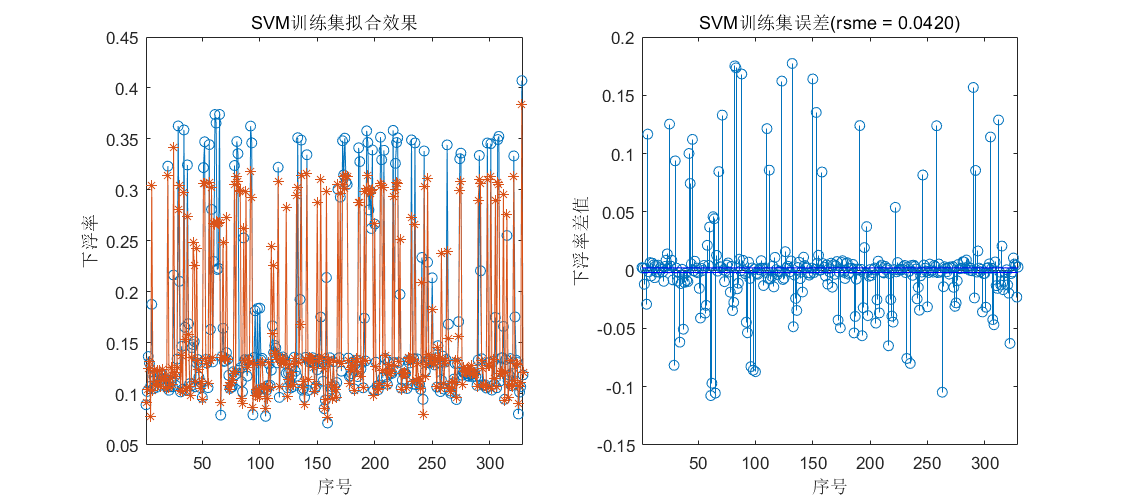

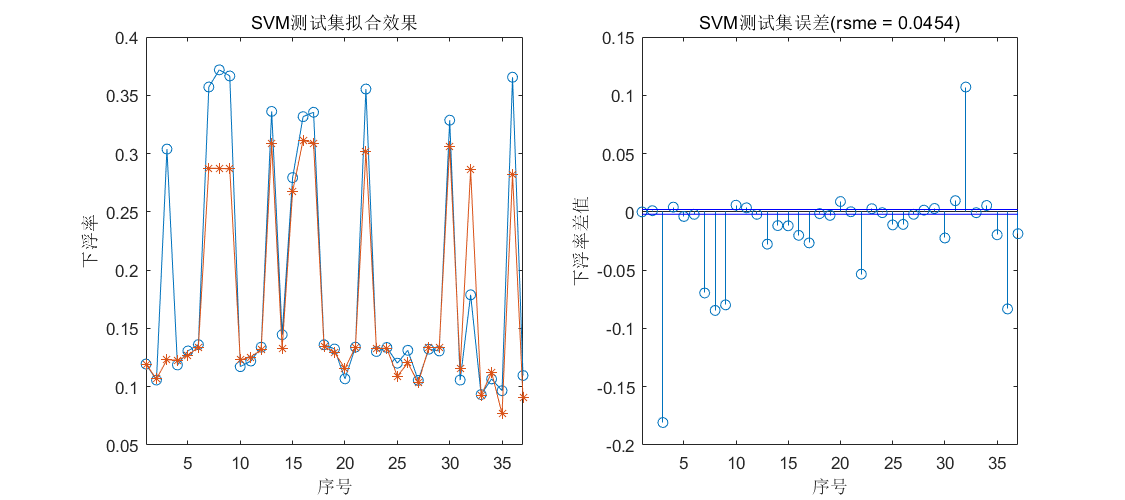

#### 资质要求、最高报价、下浮率、工资、开标时间、镇区、计划工期、P值下浮率 → P值下浮率

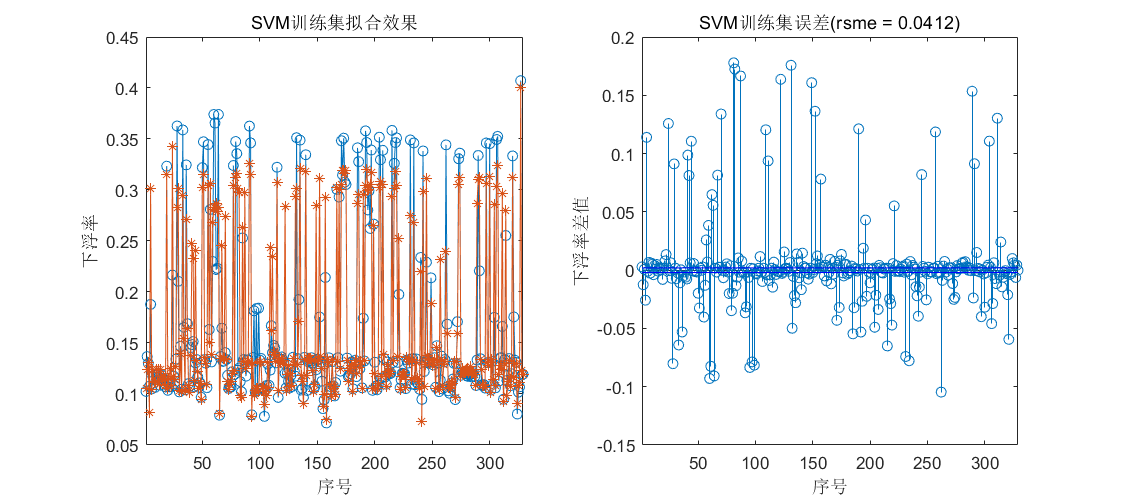

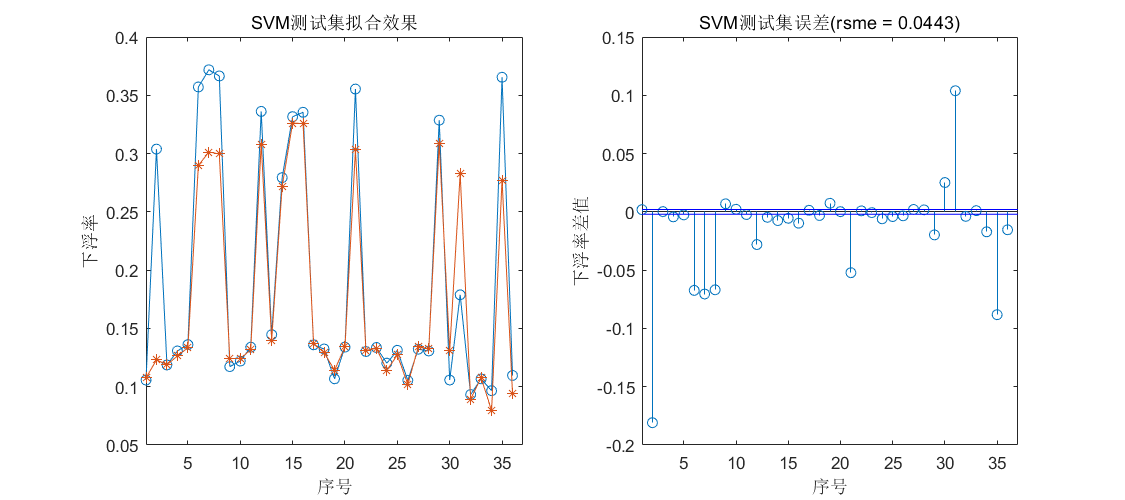

#### 选择下浮率小于 0.15 部分：资质要求、最高报价、下浮率、工资、开标时间、镇区、计划工期 → P值下浮率

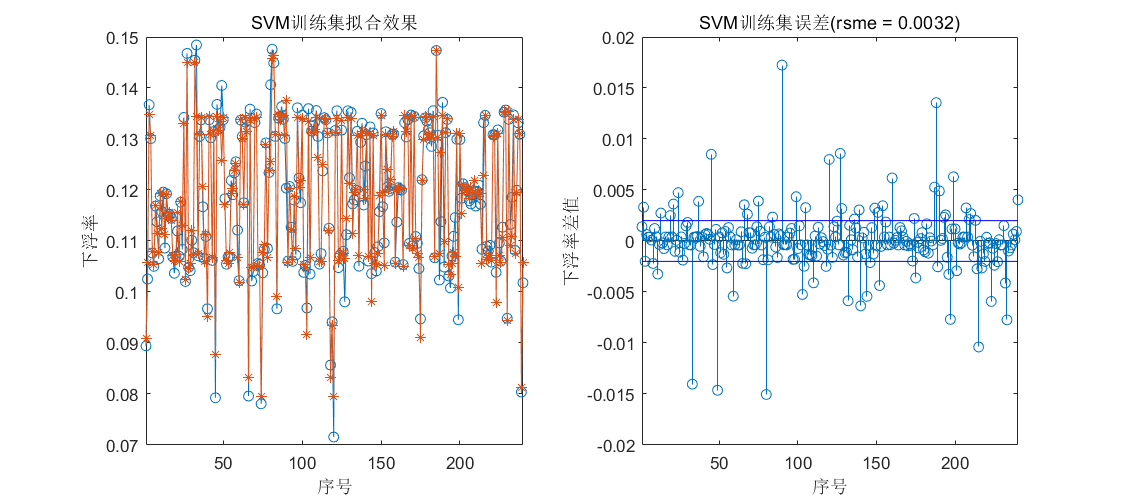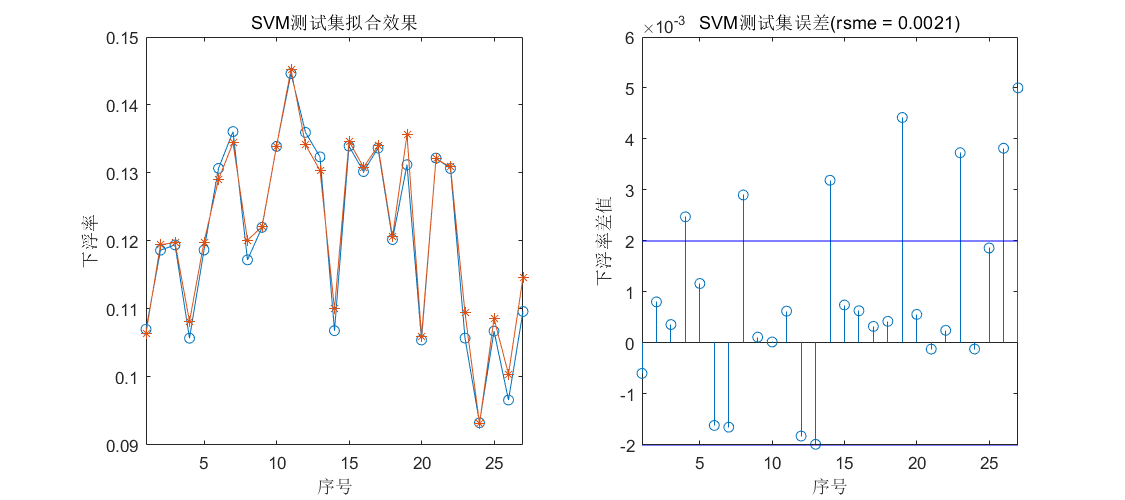

clear;clc;close all;
%%%%%%%%%%%%%%%%%%%%%%%%%% 加载数据
filename = '\\longde\longde\008-投标中心\006-数据分析中心\分析结果汇总\zb_ML.xlsx';
file = readtable(filename, 'Sheet', 1, 'VariableNamingRule', 'preserve');
data = table2array(file(:, 2:end));
% 数据筛选
indx = find(data(:, end) <= 0.15);
data = data(indx, :);
% 输入、输出数据提取
% 方式一：已知信息 → 未知信息
output = data(:, end);
input = data(:, 1:end-2);
% 方式二：已知信息 + 之前的结果信息 → 未知信息
% output = data(2 : end, end);
% input = [data(2 : end, 1 : end-2), data(1 : end-1, end)];
train_number = floor(0.9 * size(data, 1));
test_number = size(data, 1) - train_number;
input_train = input(1:train_number, :);
output_train = output(1:train_number, :);
input_test = input(train_number+1 : end, :);
output_test = output(train_number+1 : end, :);
% 归一化
[Yinput_train, PSinput_train] = mapminmax(input_train');
[Youtput_train, PSoutput_train] = mapminmax(output_train');
Yinput_test = mapminmax('apply', input_test', PSinput_train);
Yinput_train = Yinput_train';
Youtput_train = Youtput_train';
Yinput_test = Yinput_test';
%%%%%%%%%%%%%%%%%%%%%%%%%% 交叉校验，获取最佳的 c 和 g 参数
best_c = 0;
best_g = 0;
best_mse = Inf;
log2c = -4 : 0.5 : 4;
log2g = -4 : 0.5 : 4;
cg = nan(length(log2c), length(log2g));
for i = 1:length(log2c)
    for j = 1:length(log2g)
        c = 2^log2c(i);
        g = 2^log2g(j);
        % -v 交叉验证参数，在训练的时候需要
        cmd = sprintf('-v 3 -c %f -g %f -s 3 -t 2 -p 0.1 -h 0', c, g);
        cg(i, j) = svmtrain(Youtput_train, Yinput_train, cmd);
        % 找最小值
        if cg(i, j) < best_mse
            best_mse = cg(i, j);
            best_c = c;
            best_g = g;
        end
    end
end
% 利用最佳参数进行 SVM 网络训练
cmd = sprintf('-c %f -g %f -s 3 -t 2 -p 0.01', best_c, best_g);
model = svmtrain(Youtput_train, Yinput_train, cmd);
%%%%%%%%%%%%%%%%%%%%%%%%%% SVM 网络训练效果
[output_train_pre, ~, ~] = svmpredict(Youtput_train, Yinput_train, model);
% 反归一化
output_train_pre = mapminmax('reverse', output_train_pre', PSoutput_train);
output_train_pre = output_train_pre';
% 差值
err_train = output_train_pre - output_train;
% 均方误差
rmse_train = rms(err_train);
line_up_train = 0.002 * ones(1, train_number);
line_down_train = -0.002 * ones(1, train_number);
% 画图
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1);
plot(output_train, '-o');
xlabel('序号');
ylabel('下浮率');
title('SVM训练集拟合效果');
hold on
plot(output_train_pre, '-*');
hold off
xlim([1, train_number]);
subplot(1, 2, 2);
stem(err_train);
xlabel('序号');
ylabel('下浮率差值');
title(sprintf('SVM训练集误差(rsme = %.4f)', rmse_train));
hold on
plot(line_up_train, 'b');
plot(line_down_train, 'b');
hold off
xlim([1, train_number]);
%%%%%%%%%%%%%%%%%%%%%%%%%% SVM 网络测试效果
[output_test_pre, ~, ~] = svmpredict(output_test, Yinput_test, model);
% 反归一化
output_test_pre = mapminmax('reverse', output_test_pre', PSoutput_train);
output_test_pre = output_test_pre';
% 差值
err_test = output_test_pre - output_test;
% 均方误差
rmse_test = rms(err_test);
line_up_test = 0.002 * ones(1, test_number);
line_down_test = -0.002 * ones(1, test_number);
% 画图
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1);
plot(output_test, '-o');
xlabel('序号');
ylabel('下浮率');
title('SVM测试集拟合效果');
hold on
plot(output_test_pre, '-*');
hold off
xlim([1, test_number]);
subplot(1, 2, 2);
stem(err_test);
xlabel('序号');
ylabel('下浮率差值');
title(sprintf('SVM测试集误差(rsme = %.4f)', rmse_test));
hold on
plot(line_up_test, 'b');
plot(line_down_test, 'b');
hold off
xlim([1, test_number]);